# TentSim BAS

Uses the output of Tentsim_Preprocess.mlx to form a cumulative histogram then runs BAS analysis. Along the way, there are options to check for systematic effects (e.g. drift in event rate).

Dependancies:

'std2' requires [Image Processing Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'IP', 'focused', 'std2');).

'gmdistribution' requires [Statistics and Machine Learning Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ST', 'focused', 'gmdistribution');).

## Initialize

clear               % Clear all workspace saved variables
% UPDATE when code is revised
versionnum= 'v1p3';
disp(['Version information and details of modeling at bottom of mlx code ' ...
    'below the Information function'])

Version information and details of modeling at bottom of mlx code below the Information function


## Load preprocessed BAS parameters

Load variables and parameters stored in the output of Tentsim_Preprocess.mlx

disp('Select BAS PARAMETER file')

Select BAS PARAMETER file


[BasParamFileName,BasParamPathName] = uigetfile('*.txt','Select BAS PARAMETER file ');
disp(strcat('Using BAS parameter file path: ',BasParamPathName));

Using BAS parameter file path:/Users/JP/Desktop/BAS_Matlab/TrainingData/


disp(strcat('Using BAS parameter file: ',BasParamFileName));

Using BAS parameter file:BASparams12runs.txt


## Read .txt parameter file for BAS analysis

%The parameter file is best if in same directory as data
%Parameter file should have 5 header lines at top 

paramfile=strcat(BasParamPathName,BasParamFileName);
readmeBAS = importdata(paramfile);
preproparams=readmeBAS.data;  %vector of parameters for processing
catfilenames=readmeBAS.textdata(6:end-1,1); %last line is column headings
colheader=readmeBAS.textdata(end,:);  %has column header info

offsetA=readmeBAS.data(1);  %0 = no offset, 1 = subtr mean, 2 = subtr median, 3 = subtr rms 
offsetB=readmeBAS.data(2);
smooth=readmeBAS.data(3); %logical; smoothing of raw event histogram before BAS analysis
showfigs=readmeBAS.data(4); %logical; show or not plots of the BAS fitting to histogram


## Load preprocessed result data from a .mat Report file 

disp('Select PREPROCESSED .mat REPORT file')

Select PREPROCESSED .mat REPORT file


[BasDataFileName,BasDataPathName] = uigetfile('*.mat','Select preprocessed .mat report file ');
disp(strcat('Using preprocessed file path: ',BasDataPathName));

Using preprocessed file path:/Users/JP/Desktop/BAS_Matlab/TrainingData/Preprocess_v1p4_30Mar23-102613/


disp(strcat('Using preprocessed file: ',BasDataFileName));

Using preprocessed file:Preprocess_v1p4Preparams12runs.txt30Mar23-102613.mat


load(strcat(BasDataPathName,BasDataFileName))

%parameters from Preprocessing file saved in readmePRE structure in selected .mat file
% Do not need all of these in this code
% rawheaderlines=readmePRE.data(1);  %TAMU format for raw data files; not needed for reading
 colA=readmePRE.data(2);    %Column number where A data located; 0 if no data
 colB=readmePRE.data(3);    %Column number where B data located; 0 if no data
tbin=readmePRE.data(4);    %sampling of raw data in seconds per sample
% driftwinA=readmePRE.data(5);   %integer bin factor multiplied by 50
% driftwinB=readmePRE.data(6);   %slow drift removal
% basethreshA=readmePRE.data(7);     %low amplitude spike hash removal (integer cnts)
% basethreshB=readmePRE.data(8);     %Does change amplitude of remaining data
% corrt=readmePRE.data(9);          %Minimal time acceptable bewteen events
% dofit=readmePRE.data(10);          %Flag for Gaussian fit to events (usually 0)


## Offer option of an offset removal based on stored  median or rms of preprocessing

OBSOLETED  OffsetA ad OffsetB  Generally not used. Preprocesing handles the drift and offset removal.

if (length(handlesA.base)-1)  % checks if there is A channel data
switch (offsetA)   
    case 1
        handlesA.d(2,:)=handlesA.d(2,:)-handlesA.mean;
        handlesA.strikeamp=handlesA.strikeamp-handlesA.mean;
        qq=handlesA.d(2,:) < 0;
        handlesA.d(2,qq)=0;
        qq=handlesA.strikeamp < 0;
        handlesA.strikeamp(qq) = 0;
        disp('*** MEAN offset removed in channel A')
    case 2
        handlesA.d(2,:)=handlesA.d(2,:)-handlesA.median;
        handlesA.strikeamp=handlesA.strikeamp-handlesA.median;
        qq=handlesA.d(2,:) < 0;
        handlesA.d(2,qq)=0;
        qq=handlesA.strikeamp < 0;
        handlesA.strikeamp(qq) = 0;
        disp('*** Median offset removed in channel A')
    case 3
        handlesA.d(2,:)=handlesA.d(2,:)-handlesA.rms;
        handlesA.strikeamp=handlesA.strikeamp-handlesA.rms;
        qq=handlesA.d(2,:) < 0;
        handlesA.d(2,qq)=0;
        qq=handlesA.strikeamp < 0;
        handlesA.strikeamp(qq) = 0;
        disp('*** RMS offset removed in channel A')

end
end

if (length(handlesB.base)-1) % checks if there is B channel data
switch (offsetB)  
    case 1
        handlesB.d(2,:)=handlesB.d(2,:)-handlesB.mean;
        handlesB.strikeamp=handlesB.strikeamp-handlesB.mean;
        qq=handlesB.d(2,:) < 0;
        handlesB.d(2,qq)=0;
        qq=handlesB.strikeamp < 0;
        handlesB.strikeamp(qq) = 0;
        disp('*** Mean offset removed in channel B')
    case 2
        handlesB.d(2,:)=handlesB.d(2,:)-handlesB.median;
        handlesB.strikeamp=handlesB.strikeamp-handlesB.median;
        qq=handlesB.d(2,:) < 0;
        handlesB.d(2,qq)=0;
        qq=handlesB.strikeamp < 0;
        handlesB.strikeamp(qq) = 0;
        disp('*** Median offset removed in channel B')
    case 3
        handlesB.d(2,:)=handlesB.d(2,:)-handlesB.rms;
        handlesB.strikeamp=handlesB.strikeamp-handlesB.rms;
        qq=handlesB.d(2,:) < 0;
        handlesB.d(2,qq)=0;
        qq=handlesB.strikeamp < 0;
        handlesB.strikeamp(qq) = 0;
        disp('*** RMS offset removed in channel B')        
end
end

## Check stabilty of event rate

if length(handlesA.base(:)) ~= 1
    disp(strcat("A Channel minimum processed spike amplitude: ",num2str(handlesA.spthresh))); 
    disp(strcat("A Channel mean: ",num2str(handlesA.mean)));
    disp(strcat("A Channel median: ",num2str(handlesA.median)));
    disp(strcat("A Channel rms: ",num2str(handlesA.rms)));    
end

A Channel minimum processed spike amplitude: 15


A Channel mean: 3.5645


A Channel median: 1


A Channel rms: 10.946


if length(handlesB.base(:)) ~= 1
    disp(strcat("B Channel minimum processed spike amplitude: ",num2str(handlesB.spthresh))); 
    disp(strcat("B Channel mean: ",num2str(handlesB.mean)));
    disp(strcat("B Channel median: ",num2str(handlesB.median)));
    disp(strcat("B Channel rms: ",num2str(handlesB.rms)));    
end

B Channel minimum processed spike amplitude: 10


B Channel mean: 2.2564


B Channel median: 1


B Channel rms: 6.7879


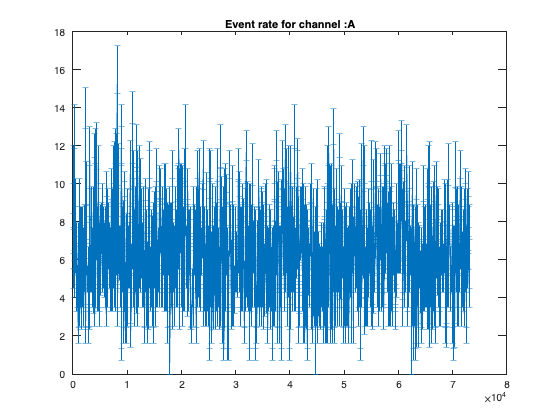


handlesA.spikebinwin = 1000;  % Use 4000 for simulated data
handlesA.stabilitythresh =  50;  % set well above lower cutoff like 3x
handlesB.spikebinwin = 1000;
handlesB.stabilitythresh =  50;

if (length(handlesA.base)-1) % checks if there is A channel data
    [handlesA,evdenA]=event_density(handlesA,'A');
end

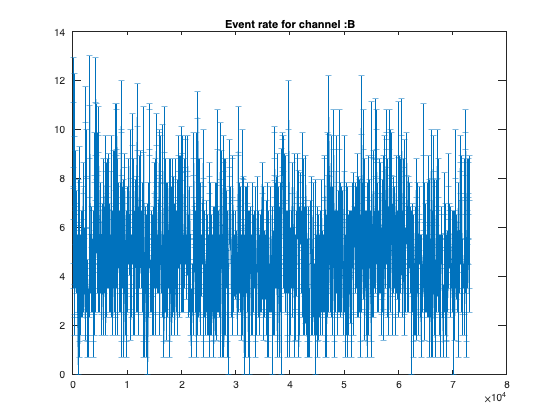

if (length(handlesB.base)-1) % checks if there is B channel data
    [handlesB,evdenB]=event_density(handlesB,'B');
end


    % Reset sliders then click to regenerate graph

## Plot data to enable determining best histogram parameters

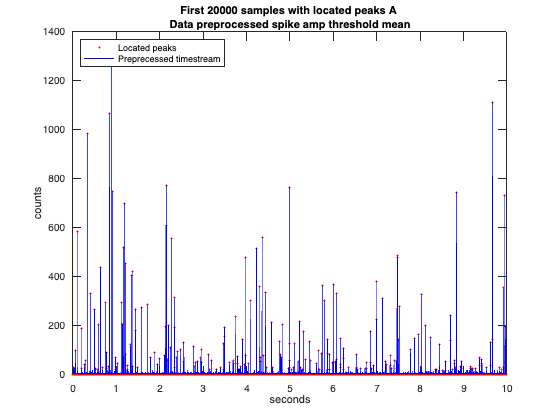

A channel: Lower acceptable event amplitude is 15


A channel: Upper acceptable event amplitude is 1508


A channel: Minimum non-zero event amplitude is 15.4678


A channel: Maximum non-zero event amplitude is 4073.5569


% Guideline info for choice of next paramentes
if colA
    minampA=min(handlesA.strikeamp(handlesA.strikeamp > 0));
    maxampA=max(handlesA.strikeamp);
    figure
    plot(handlesA.d(1,1:20000),handlesA.strikeamp(1:20000),'r.');
    hold on;
    plot(handlesA.d(1,1:20000),handlesA.d(2,1:20000),'b');
    title({"First 20000 samples with located peaks A ";...
        strcat("Data preprocessed spike amp threshold ",num2str(handlesA.spthreshtype) )})
    xlabel('seconds')
    ylabel('counts')
    legend('Located peaks','Preprecessed timestream','Location','northwest')
    hold off
    disp(strcat("A channel: Lower acceptable event amplitude is ",num2str(handlesA.spthresh)))
    disp(strcat("A channel: Upper acceptable event amplitude is ",num2str(handlesA.UB)))
    disp(strcat("A channel: Minimum non-zero event amplitude is ",num2str(minampA)))
    disp(strcat("A channel: Maximum non-zero event amplitude is ",num2str(maxampA)))

end

disp(" ")

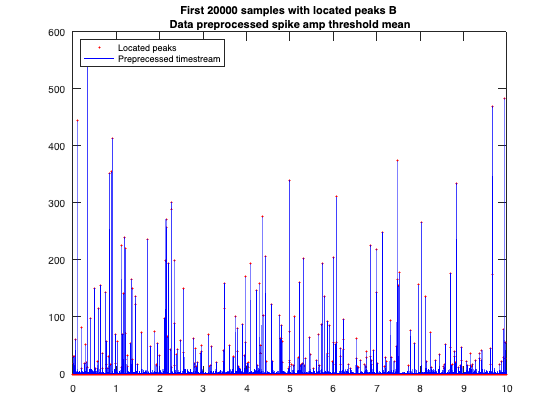

B channel: Lower acceptable event amplitude is 10


B channel: Upper acceptable event amplitude is 1001


B channel: Minimum non-zero event amplitude is 10.1671


B channel: Maximum non-zero event amplitude is 3025.2385


if colB
    minampB=min(handlesB.strikeamp(handlesB.strikeamp > 0));
    maxampB=max(handlesB.strikeamp);
    figure
    plot(handlesB.d(1,1:20000),handlesB.strikeamp(1:20000),'r.');
    hold on;
    plot(handlesB.d(1,1:20000),handlesB.d(2,1:20000),'b');
    title({"First 20000 samples with located peaks B ";...
        strcat("Data preprocessed spike amp threshold ",num2str(handlesB.spthreshtype) )})
    legend('Located peaks','Preprecessed timestream','Location','northwest')
    hold off
    disp(strcat("B channel: Lower acceptable event amplitude is ",num2str(handlesB.spthresh)))
    disp(strcat("B channel: Upper acceptable event amplitude is ",num2str(handlesB.UB)))
    disp(strcat("B channel: Minimum non-zero event amplitude is ",num2str(minampB)))
    disp(strcat("B channel: Maximum non-zero event amplitude is ",num2str(maxampB)))
end

## Find photon histogram

%Initialize BAS results
logedgeA=0; logedgeB=0; uncertnA=0; uncertnB=0;
qA=0; qB=0; nA=0; nB=0; numA=0; numB=0; cummA=0;  cummB=0; nseg=1; part=1;

% Allow for unweighted bins to handle undersampling, etc.
         unwgtbins=false

unwgtbins = logical
   0


nbinsA = 13

ptypeA = "Log"

RangeoverideA = logical
   0


Bin edges: 16.5      27.010484      44.216137      72.381773      118.48889      193.96621      317.52249      519.78401      850.88593      1392.8995      2280.1751      3732.6444      6110.3353


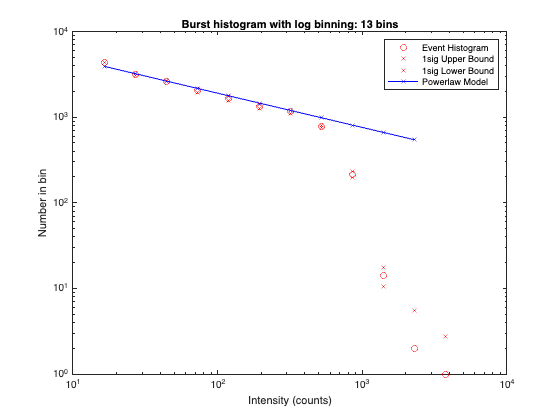

         if unwgtbins
                    leftpad = 2
                    rightpad = 0
         else
             leftpad=0;
             rightpad=0;
         end


if colA
                    nbinsA =13
                    ptypeA = "Log"
% See Minimum/Maximum non-zero event amplitude output to set values

                    minthreshA = 1.1 * handlesA.spthresh; %based on 1/200 dynamic range
                    maxthreshA = 1.5 * max(handlesA.strikeamp);  %based on top event

%  Allow manual overide
         RangeoverideA=false
         if RangeoverideA
                    minthreshA = 35
                    maxthreshA = 8000
         end
          
 [logedgeA nA uncertnA]=photon_hist(handlesA,datastatA,nbinsA,minthreshA,maxthreshA,tbin,ptypeA,nseg,part);    

end

nbinsB = 13

ptypeB = "Log"

RangeoverideB = logical
   0


Bin edges: 11      18.169691      30.012515      49.574374      81.886458      135.25924      223.41986      369.04271      609.58109         1006.9      1663.1874      2747.2364      4537.8578


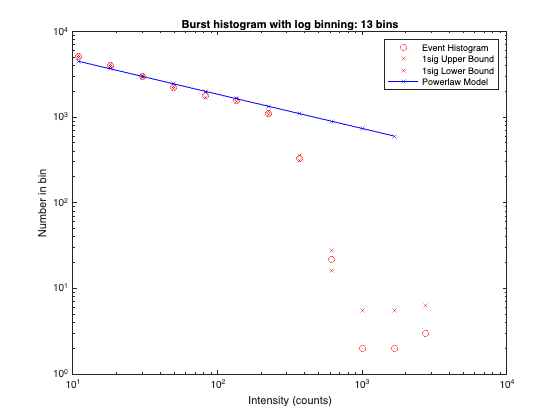

if colB
                    
                    nbinsB =13
                    ptypeB = "Log"
% See Minimum/Maximum non-zero event amplitude output to set values

                    minthreshB = 1.1 * handlesB.spthresh; %based on 1/200 dynamic range
                    maxthreshB = 1.5 * max(handlesB.strikeamp);  %based on top event

%  Allow manual overide
         RangeoverideB=false
         if RangeoverideB
 
                    minthreshB = 111
                    maxthreshB = 20000
         end
                    
 [logedgeB nB uncertnB]=photon_hist(handlesB,datastatB,nbinsB,minthreshB,maxthreshB,tbin,ptypeB,nseg,part);


end

## Calculate BAS distribution

 % Generate multiple histograms using Gaussian distribtuion approx for each
 % bin where mean is nA or nB and sigma is uncertnA uncertnB
 
 numbassim = 10 % number of simulations to generate from bins

numbassim = 10

uncertfactorA = 2

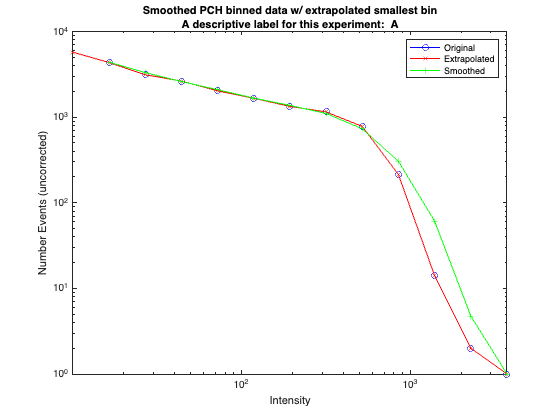

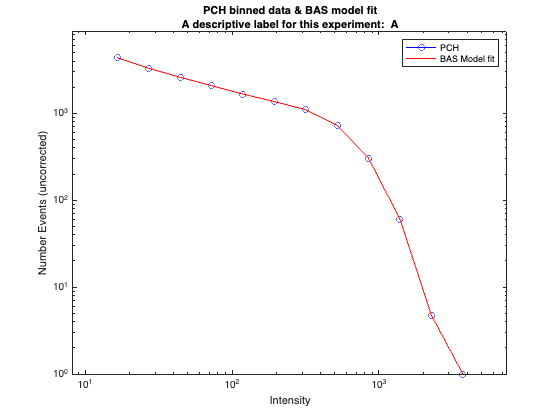

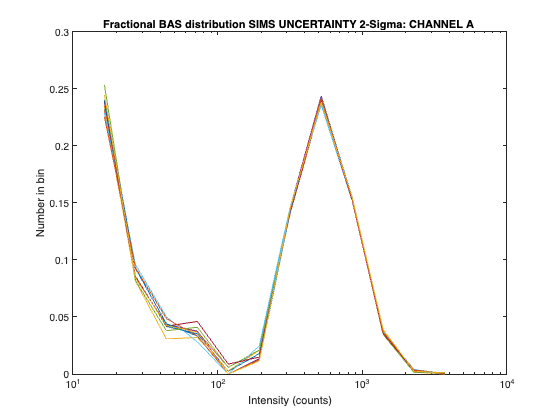

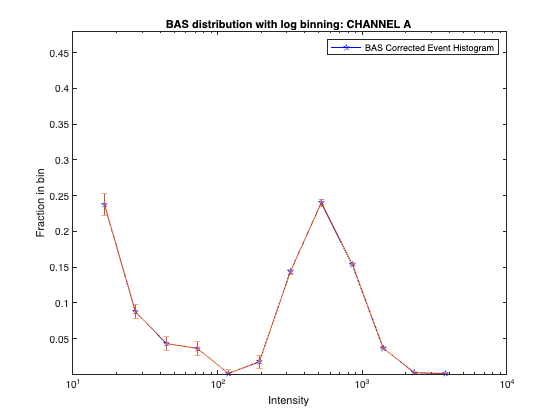

 
if colA
    
 uncertfactorA = 2 % number sigma in gmdistrib about mean values nA
 
 gm = gmdistribution(nA,uncertnA*uncertfactorA);
 nAsim  = random(gm,numbassim);
 numAsim=zeros(numbassim,length(nA));
 qAsim=zeros(numbassim,length(nA));
 cummAsim=zeros(numbassim,length(nA));
 
 for k=1:numbassim
    nAsim_k=nAsim(k,:);
    [ numAtemp, qAtemp , cummAtemp] = burst_analysis( logedgeA, nAsim_k , smooth, 0, 0, leftpad, rightpad); %no figs
    numAsim(k,:)=numAtemp;
    qAsim(k,:)=qAtemp;
    cummAsim(k,:)=cummAtemp;
 end  
handlesA.numAuncert=std(numAsim,1);

% Find mean BAS values
plotlabelA= strcat("A descriptive label for this experiment: "," A");    
[ numA, qA , cummA] = burst_analysis( logedgeA, nA , smooth, plotlabelA, showfigs, leftpad,rightpad);

%Plot simulated results 
figure
    semilogx(logedgeA,numAsim/sum(numA))
    title("Fractional BAS distribution SIMS UNCERTAINTY 2-Sigma: CHANNEL A ")
    xlabel('Intensity (counts)')
    ylabel('Number in bin')

%Plot NORMALIZED mean BAS results 
% Normalize intensity based on event distribution
%Find centroid
centroidIA=sum(logedgeA.*numA')/sum(numA);

figure
semilogx(logedgeA,numA/sum(numA),'-bp')
hold on
    errorbar(logedgeA,numA'/sum(numA),2*handlesA.numAuncert/sum(numA))
%    xlim([logedgeA(1),logedgeA(end)]);
ylim([2*max(numA(:)/sum(numA))*.001,2*max(numA(:)/sum(numA))]);  %defaults to 3 orders of range from max
title("BAS distribution with log binning: CHANNEL A ")
xlabel('Intensity ')
ylabel('Fraction in bin')
legend('BAS Corrected Event Histogram','Location','northeast')
hold off
 
end

uncertfactorB = 2

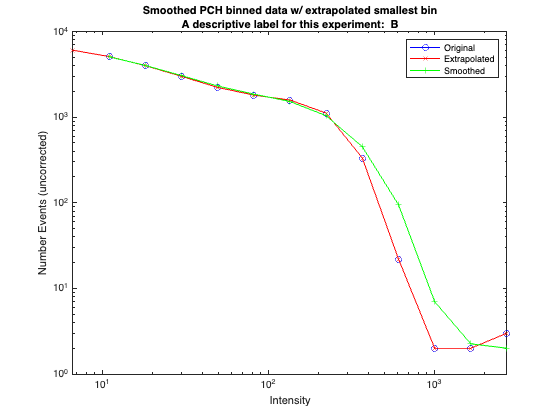

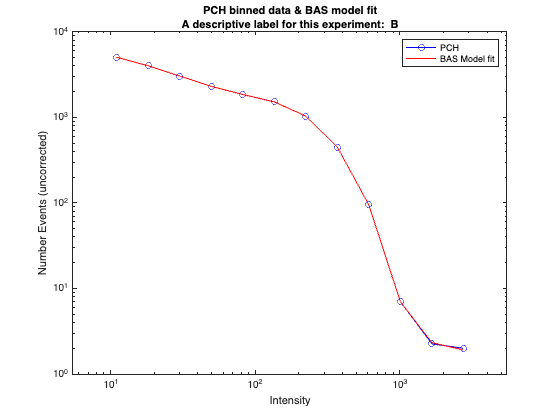

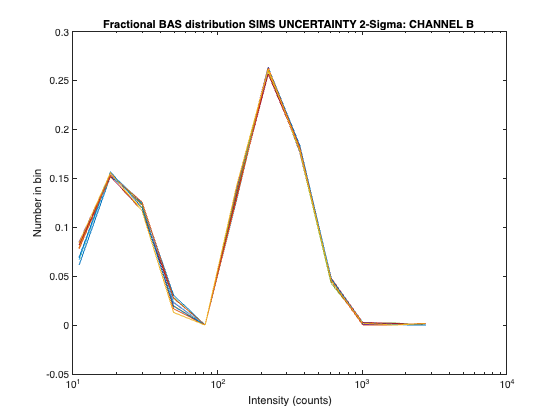

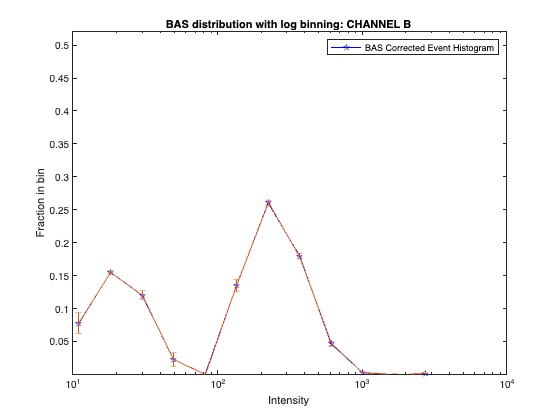



if colB

 uncertfactorB = 2 % number sigma in gmdistrib about mean values nA
 
 gm = gmdistribution(nB,uncertnB*uncertfactorB);
 nBsim  = random(gm,numbassim);
 numBsim=zeros(numbassim,length(nB));
 qBsim=zeros(numbassim,length(nB));
 cummBsim=zeros(numbassim,length(nB));

 for k=1:numbassim
    nBsim_k=nBsim(k,:);
    [ numBtemp, qBtemp , cummBtemp] = burst_analysis( logedgeB, nBsim_k , smooth, 0, 0, leftpad, rightpad); %no figs
    numBsim(k,:)=numBtemp;
    qBsim(k,:)=qBtemp;
    cummBsim(k,:)=cummBtemp;
 end  
 handlesB.numBuncert=std(numBsim,1);

%Find mean BAS results
  plotlabelB= strcat("A descriptive label for this experiment: "," B");
  [ numB, qB , cummB] = burst_analysis( logedgeB, nB , smooth, plotlabelB, showfigs, leftpad, rightpad);
  
%Plot simulated results 
  figure
    semilogx(logedgeB,numBsim/sum(numB))
    title("Fractional BAS distribution SIMS UNCERTAINTY 2-Sigma: CHANNEL B ")
    xlabel('Intensity (counts)')
    ylabel('Number in bin')

%Plot NORMALIZED mean values of BAS 
% Normalize intensity based on event distribution

    figure
    semilogx(logedgeB,numB/sum(numB),'-bp')
    hold on
        errorbar(logedgeB,numB'/sum(numB),2*handlesB.numBuncert/sum(numB))
    ylim([2*max(numB(:)/sum(numB))*.001,2*max(numB(:)/sum(numB))]);  %defaults to 3 orders of range from max
    title("BAS distribution with log binning: CHANNEL B ")
    xlabel('Intensity ')
    ylabel('Fraction in bin')
    legend('BAS Corrected Event Histogram','Location','northeast')
    hold off
    
end

## Save results to .mat file and a pdf report

savebasresults=true

savebasresults = logical
   1


%Save processing 
%Get information about this data run and create a director for this data store
[basfile, tstr]=Information(versionnum);

tstr = datetime
   30Mar23-103304


version number:v1p4


timestr=string(tstr);
newdir=strcat(basfile,'_',timestr)

newdir = "BAS_v1p4_30Mar23-103304"

mkdir(newdir)


if savebasresults
   savebasdone=Save_BAS(newdir,BasParamPathName,BasDataFileName,handlesA,handlesB,qA,qB,logedgeA,logedgeB, nA, nB, numA, numB, cummA, cummB, versionnum)
end

tstr = datetime
   30Mar23-103304


version number:v1p4


savebasdone = 1

# Part II

## FUNCTIONS

## Display burst event rate 

function [handles,evden]=event_density(handles,channel)
%Calc. event denisty vs time for specified window size
% evendenagain='y';
%while (evendenagain == 'y')


    eventwin=fix(handles.spikebinwin); 
    evden=-ones(1,size(handles.strike,2)); 
    evdenstd=-ones(1,size(handles.strike,2));
    for i=1:eventwin:size(handles.strike,2)-eventwin+1
        binval=zeros(1,10);
        for j=1:10
            a=find(handles.strikeamp(i+(j-1)*eventwin/10:i+eventwin/10*j-1) > handles.stabilitythresh);
            binval(j)=size(a,2);
        end
        evden(i)=sum(binval); evdenstd(i)=std2(binval);
    end
    evdenindex=find(evden>=0);

    % figure
    errorbar((evdenindex+eventwin/2)*.05,evden(evdenindex),evdenstd(evdenindex));
    title(strcat('Event rate for channel :',channel))
    handles.evdentime=(evdenindex+eventwin/2)*.05;
    handles.evden=evden(evdenindex);    
    handles.evdenstd=evdenstd(evdenindex);
    handles.eventwin=eventwin;

%    evendenagain=input('Again(y/n): ','s');
%end %while

evden=1; %Completed

end

## Determine photon histogram

function [logedge,n,uncertn]=photon_hist(handles,datastat,nbins,minthresh,maxthresh,tbin,ptype,nseg,part)
% Calculate photon count histogram with input binning parameters 
% returns binning left edges, number in bin and estimate of uncertainty in binning 
% tbin =  size of bins in seconds
% ptype choose linear or logarithmic binning; use log for usual BAS
% now
% nseg
% part

peakloc=find(handles.strikeamp > 0);  %indicies to all events found
peakloc=peakloc(find(peakloc > 15)); %find only events +/- 15 bins from ends
peakloc=peakloc(find(peakloc < size(handles.strikeamp,2)-15));
npeaks=size(peakloc,2);  % Number of peaks to consider

%params=struct('mean',[1:npeaks],'sig',[1:npeaks],'A',[1:npeaks]);

peaks=handles.strikeamp(peakloc); %not really needed, just saves typing

edgemn=(log10(minthresh));
edgemx=(log10(maxthresh));

%edgeexp=[edgemn:edgemx];
logedge = logspace(edgemn,edgemx,nbins);
disp(strcat("Bin edges: ",num2str(logedge)))

if (ptype == 'Linear') 
    [n,xbins]=hist(peaks,nbins);
    figure
    loglog(xbins,n,'ro');
    title(strcat("Burst histogram with linear binning: ",num2str(nbins)," bins"))
    xlabel('Intensity (counts)')
    ylabel('Number in bin')
else
%    [n,xbins]=histc(peaks,logedge); %older 2013 command
    [n,edges,xbins]=histcounts(peaks,logedge); %histcounts returns logedege into
    % edges and xbins is as before; n has 1 fewer elements so use
    % logedge(1:end-1) below
    figure
    loglog(logedge(1:end-1),n,'ro');
%Find an estimate of uncertainties in each bin by breaking  data set into
%quarters
    quar=fix(length(peaks)/4);
    [nq1,edges]=histcounts(peaks(1:quar),logedge);
    [nq2,edges]=histcounts(peaks(quar+1:2*quar),logedge);
    [nq3,edges]=histcounts(peaks(2*quar+1:3*quar),logedge);
    [nq4,edges]=histcounts(peaks(3*quar+1:end),logedge);
    avnq =(nq1+nq2+nq3+nq4)/4; %avg quadrature number of events
    unc=sqrt(((nq1-avnq).^2+(nq2-avnq).^2+(nq3-avnq).^2+(nq4-avnq).^2)/4);
    uncertn=4*unc; %uncertainty estimate for full data bins; Why the 4* ??
    hold on
    loglog(logedge(1:end-1),n+uncertn,'rx');  
    loglog(logedge(1:end-1),n-uncertn,'rx');  
    hold off
    
    logedge=logedge(1:end-1); %so that only bin left edges are passed back


%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=n(3); %pin to third data value - first sometimes compromised by binning
b=(logedge(3)).^powern;
hold on
loglog(logedge(1:end-1),a/b*(logedge(1:end-1)).^powern,'-bx')
hold off
subtitle=strcat("Fit Powerlaw of index: ",num2str(powern));
    title(strcat("Burst histogram with log binning: ",num2str(nbins)," bins"))
    xlabel('Intensity (counts)')
    ylabel('Number in bin')
    legend('Event Histogram','1sig Upper Bound','1sig Lower Bound', 'Powerlaw Model','Location','northeast')


end

end

## Calculate BAS distribution

Exactly from burst_analysis_JP.m used for MCBAS paper

function [ num, q , cumm] = burst_analysis( logedge, n , smooth, plotlabel, showfigs, leftpad, rightpad)
%This program runs burst analysis and outputs the event density
% Plotlabel is a string added to PCH diagnostic figure 
% smooth:  1 or anything else .   1 means use smoothing function on PCH before BAS
% plotlabel:   a string to be added to plots that indicates data type, name, etc.
% singlecolor:  1 or anything else . 1 means single color BAS so display more plots
% 

sx=logedge;
sn=n;
ind=.40;  %Set by Tetraspec beads 28 Aug 2020
    
%sn=smooth(sx,sn,'lowess');  %rlowess will round off steep spectra
%sn=sn';

if (smooth == 1)
    [sn,sx]=burst_smooth_JP(sx,sn,plotlabel,showfigs);
%    [sn,sx]=burst_smooth(sx,sn);
end
%sx=sx(1:(end-1));
% save 'inter_sn.mat' sn;

%Extend vector length  to 28 by padding with zeros
ngood=size(sx(:),1);

ndew=28-ngood;
if (ndew > 0)
    pad=ones(ndew,1)/100;
    sx=[pad'/1e6,sx]';
    sn=[pad',sn]';
end

%x=logedge(1:28)';
%y=n';
xfer=1./(sx.^ind);
mask0=zeros(1,28);
mask1=ones(1,28);
%mod=xfer;
mod=mask1';
for i=27:-1:1
    mask_i=[mask1(1:i),mask0(i+1:end)]';
%    mod=[mod xfer.*mask_i];
    mod=[mask_i mod];  %I reversed this from before because amp was reversed
end %for

%a=mod\n;


%Use of FIT routine
x=sx; y=sn;
 formula_a='(a1*m1+a2*m2+a3*m3+a4*m4+a5*m5+a6*m6+a7*m7+a8*m8+a9*m9+a10*m10+a11*m11+a12*m12)./(x.^0.40)';
 formula_b='(a13*m13+a14*m14+a15*m15+a16*m16+a17*m17+a18*m18+a19*m19+a20*m20+a21*m21+a22*m22+a23*m23+a24*m24)./(x.^0.40)';
 formula_c='(a25*m25+a26*m26+a27*m27+a28*m28)./(x.^0.40)';
 formula=[formula_a,'+',formula_b,'+',formula_c];
 mymodel = fittype(formula,'problem',{'m1','m2','m3','m4','m5','m6','m7','m8','m9','m10','m11','m12', ...
     'm13','m14','m15','m16','m17','m18','m19','m20','m21','m22','m23','m24','m25','m26','m27','m28' });
 opts = fitoptions(mymodel);
 opts.Lower=zeros(1,28);
 
 %%%%
 opts.Robust='Bisquare';
 opts.MaxFunEvals=10000;
 %%%%
 %%opts.Upper=max(y'.*(x'.^0.40)/15,ones(1,28)); %%max(y'/5,ones(1,28));
 opts.Upper=10000*ones(1,28); 
 
 %  Option for deweightig lowest intensity
 opts.Weights=ones(1,28); 
 if leftpad
     opts.Weights(1:ndew+leftpad)=0; %Unweight padded values
 else
     opts.Weights(1:ndew)=0;
 end
 if rightpad
     opts.Weights(end-rightpad) = 0;
 end

% get(opts); %print out options
[fit4,gof4,out4] = fit(x,y,mymodel,opts,'problem',{mod(:,1),mod(:,2),mod(:,3),mod(:,4),mod(:,5),mod(:,6), ...
   mod(:,7),mod(:,8),mod(:,9),mod(:,10),mod(:,11),mod(:,12), ... 
   mod(:,13),mod(:,14),mod(:,15),mod(:,16),mod(:,17),mod(:,18), ...
   mod(:,19),mod(:,20),mod(:,21),mod(:,22),mod(:,23),mod(:,24),...
   mod(:,25),mod(:,26),mod(:,27),mod(:,28)});

amp=[fit4.a1,fit4.a2,fit4.a3,fit4.a4,fit4.a5,fit4.a6,fit4.a7,fit4.a8,fit4.a9,fit4.a10,...
    fit4.a11,fit4.a12,fit4.a13,fit4.a14,fit4.a15,fit4.a16,fit4.a17,fit4.a18,fit4.a19,fit4.a20,...
    fit4.a21,fit4.a22,fit4.a23,fit4.a24,fit4.a25,fit4.a26,fit4.a27,fit4.a28];

%amp=amp.*opts.weights;
%reverse order because mod's are reversed in order - fix later
%ord=[28:-1:1];
%amp=amp(ord);
% Remove padding
amp=amp(ndew+1:end);
sx=sx(ndew+1:end); sn=sn(ndew+1:end); xfer=xfer(ndew+1:end);


del=zeros(1,ngood);
for i=ngood-1:-1:1
    del(i)=xfer(i)*sum(amp(i+1:end));
%    del(i)=xfer(i)*sum(sn(i+1:end)./xfer(i+1:end));
end; %for

del=del';
rv=[ngood:-1:1];
q=fit4(x); q=q(ndew+1:end);
%nn=xfer.*(amp); %Same as num except with correction for log binning
nn=xfer.*(amp'); %Same as num except with correction for log binning

num=q-del;  %net number of events in each bin corrected for larger species
cumm=cumsum(q(rv)-del(rv)); %cumulative sum from largest to smallest
cumm=cumm(rv); %reorder for plotting
% save 'inter_q.mat' q;
% save 'inter_1BAS.mat' q cumm num sx sn;

% Display some figures
if (showfigs)
        
    figure
    loglog(sx,sn,'-bo');  %original PCH data
    hold on
    loglog(sx,q,'-r');  %BAS model fit
    subtitle = plotlabel;
    title({'PCH binned data & BAS model fit';subtitle})
    set(gca,'XLim',[sx(1)/2,2*sx(end)]);
    set(gca,'YLim',[1,2*max(q(:))]);
    xlabel('Intensity')
    ylabel('Number Events (uncorrected)')
    legend('PCH','BAS Model fit');
    hold off
% 
%     figure
%     loglog(sx,num,'-bo');  %BAS number density
%     title('BAS corrected Number Density vs Intensity')
%     suptitle(plotlabel)
%     xlabel('Intensity')
%     ylabel('Number Events (BAS Corrected)')
%     set(gca,'YLim',[1,1000],'XLim',[sx(1),sx(end)]);
%     legend('BAS data');
% 
    
end;

end

## Smooth Raw Event Histogram before BAS

Code taken direct from burst_smooth_JP.m

function [sns,sx] = burst_smooth_JP(sx,sn,plotlabel,showfigs)
% Take in PCH data that is LOGARYTHMICALLY binnned then extrapolate a next
% lower intensity event number for sn. Use this to apply Daniel's smoothing 
% filter. Concern is that that filter systematically lowers value of first
% bin causing BAS to show population drop that isn't real. Also, the filter
% removed the largest intensity bin. Here the extrapolation mostly removes
% low intensity bias but largest bin is still lost so original data largest
% bin is simply concatenated. This could be an issue for a spuriously large
% value of events in largest bin.

dlogbin=mode(diff(log10(sx(:))));  %Find logrythmic spacing between bins
%This means log10(sx(n))-log10(sx(n-1))=dlogbin
%or sx(n-1)=sx(n)/(10^dlogbin)
% Use this to extrapolate the next lower intensity bin
extrapbin=sx(1)/(10^dlogbin);

%Use spline interp to estimate a continuance of sn data
x=sx;
y=sn;
extrapx=[extrapbin,sx];
nexty=max([csapi(x,y,extrapbin),y(1),y(2)]); %Follow data trend up and prevents downward
extrapy=[nexty,sn];

if (showfigs)
    figure
    loglog(sx,sn,'-bo');  %original DATA
    hold on
    loglog(extrapx,extrapy,'-rx');   % include extrapolated smaller point
    subtitle = plotlabel;
    title({'Smoothed PCH binned data w/ extrapolated smallest bin';subtitle})
    xlabel('Intensity')
    ylabel('Number Events (uncorrected)')
    set(gca,'XLim',[extrapx(1),extrapx(end)]);
end;

% Daniel's averaging method that biases down first data point (hence
% extrapolation). Also, largest intensity bin lost in this averaging so add
% min of original last sn and new extrapolate 2nd to last data value. 

avglow=(extrapy(1:(end-1))+extrapy(2:end))/2;
avghi=[extrapy(1),avglow];
avgn=(avglow+avghi(1:end-1))/2;
sns=[avgn,min(sn(end-1),sn(end))];  %Add a last data value consistent with 
% original data unless larger than smoothed last value - prevents aphysically 
%large 1st value

if (showfigs)
    %Add smooth to PCH to see if it looks ok
    loglog(extrapx(2:end),sns(2:end),'-g+');
    legend('Original','Extrapolated','Smoothed')
end;

%%Time to examine smooth result
pause(3)

%Continue with smooth PDH data removing 1st extrapolated point
sns=sns(2:end);  

end


## Save BAS results to .mat and PDF report

function savepredone=Save_BAS(newdir,PrePathName,PreFileName,handlesA,handlesB,qA,qB,logedgeA,logedgeB, nA, nB, numA, numB, cummA, cummB, versionnum)
% save data and results

[basfile, tstr]=Information(versionnum);

timestr=string(tstr);
prefilenamereport=strcat(PrePathName,newdir,'/',basfile,PreFileName,timestr,'OUTPUT.pdf');
prefilenamesave=strcat(PrePathName,newdir,'/',basfile,PreFileName,timestr,'RESULTS.mat');
prefilenameprog=strcat(PrePathName,newdir,'/',basfile,PreFileName,timestr,strcat(basfile,'.mlx'));
        
% % Write our a run report PDF
% %import matlab.internal.liveeditor.LiveEditorUtilities
% matlab.internal.liveeditor.openAndConvert(which(string(prefilenameprog)),char(prefilenamereport));

%Save all Matlab variables and states
save(prefilenamesave)
savepredone=1;
end


## Outputs code version information 

function [basfile, tstr]=Information(versionnum)
% Display version and hold introductory information


basfile=strcat('BAS_',versionnum);

tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'

disp(strcat('version number: ',versionnum))
%disp(strcat('Output file name: ',strcat(basfile,'-Report',string(tstr),'.pdf')))

end
